addpath('utils');

## Read data

dataset  = '2sticks_sheet'

dataset = '2sticks_sheet'

dataset = 'stick_between_sheets'

dataset = 'stick_between_sheets'

X = load(['datasets\synthetic\3clusters\',dataset,'\X.csv']);
labels = load(['datasets\synthetic\3clusters\',dataset,'\labels.csv']);
Y = load(['datasets\synthetic\3clusters\',dataset,'\Y.csv']);

## Equivalent usage of DAPCA

alpha = 1;
[V1, D1, PX, PY] = DAPCA(X, labels, [], 3, 'alpha', alpha);

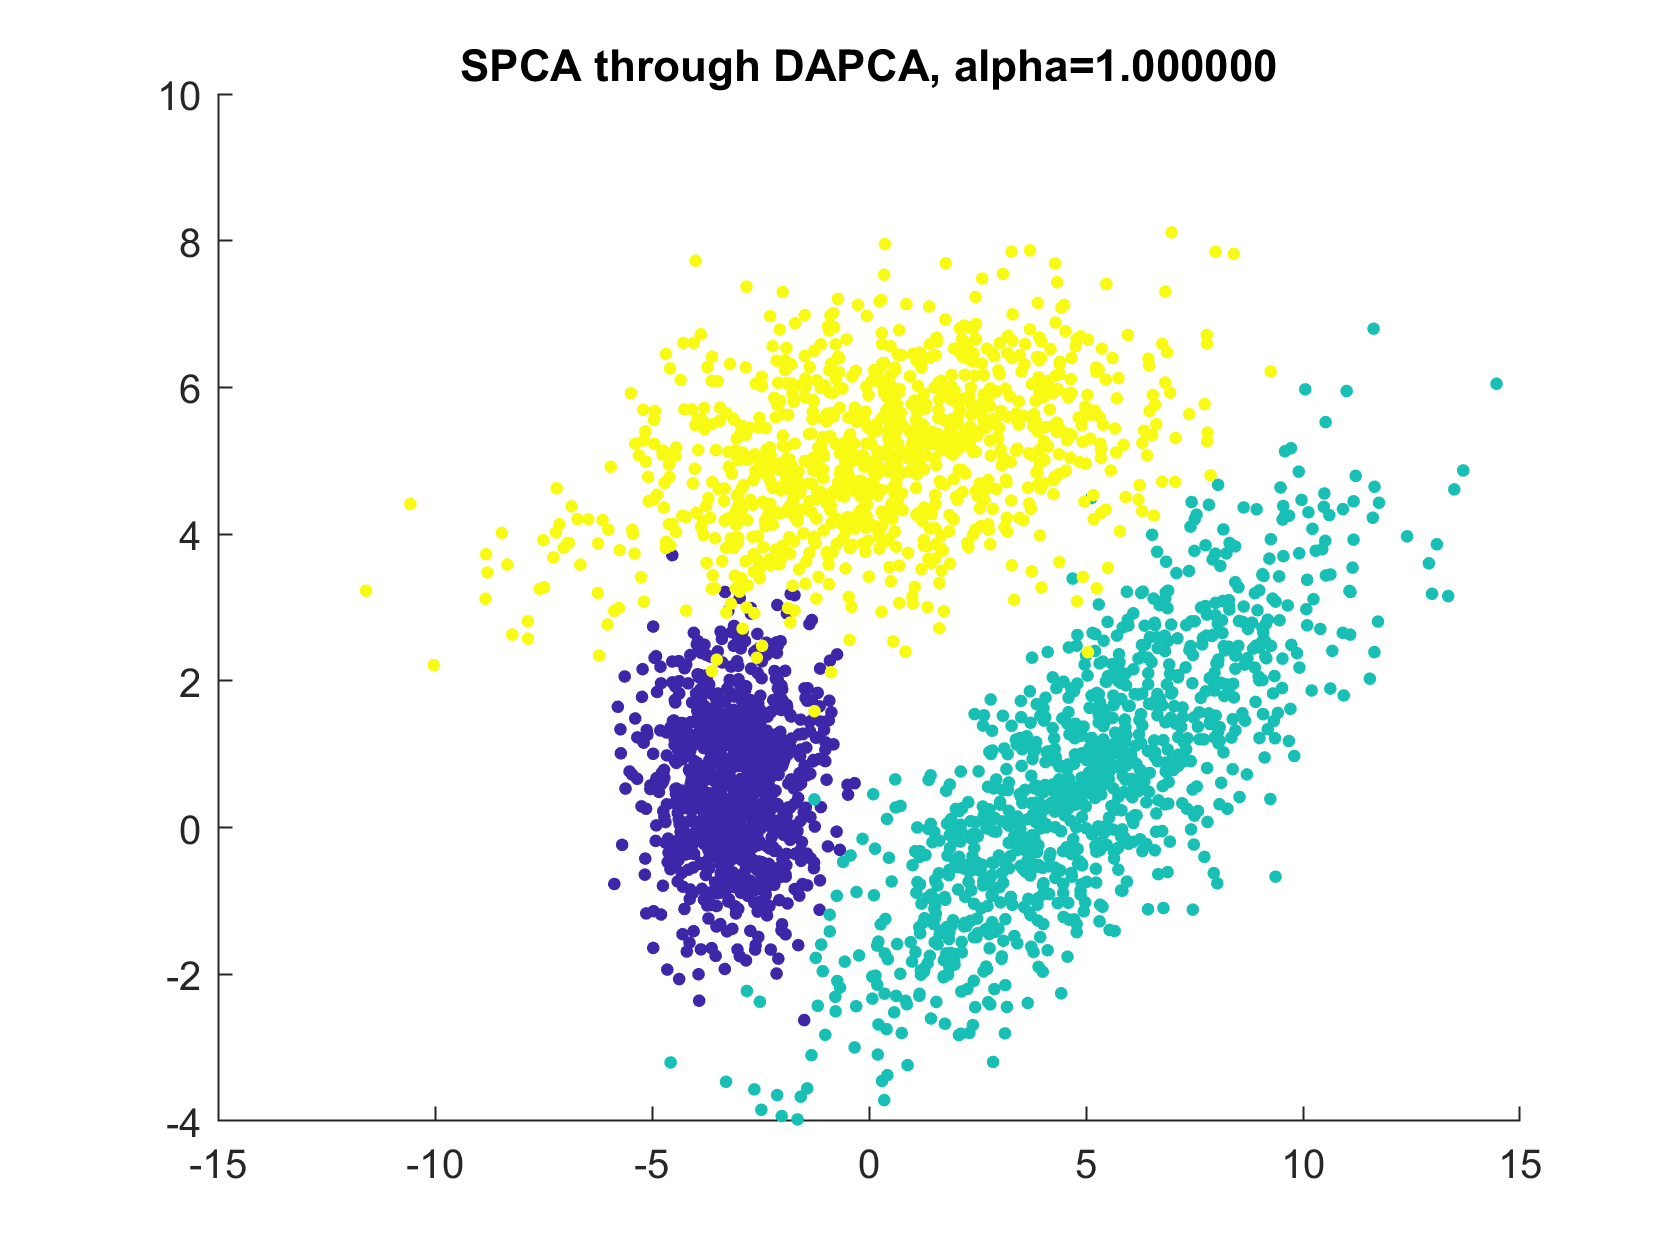

% Drawing
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
title(sprintf('SPCA through DAPCA, alpha=%f', alpha));
saveFigures(sprintf('Figures\\DAPCA_alpha_%4.2f.png', alpha));

## Variation of delta

alpha = 1;
delta = [0.1, 0.2, 5];
[V2, D2, PXd, PYd] = DAPCA(X, labels, [], 2, 'alpha', alpha, 'delta', delta);

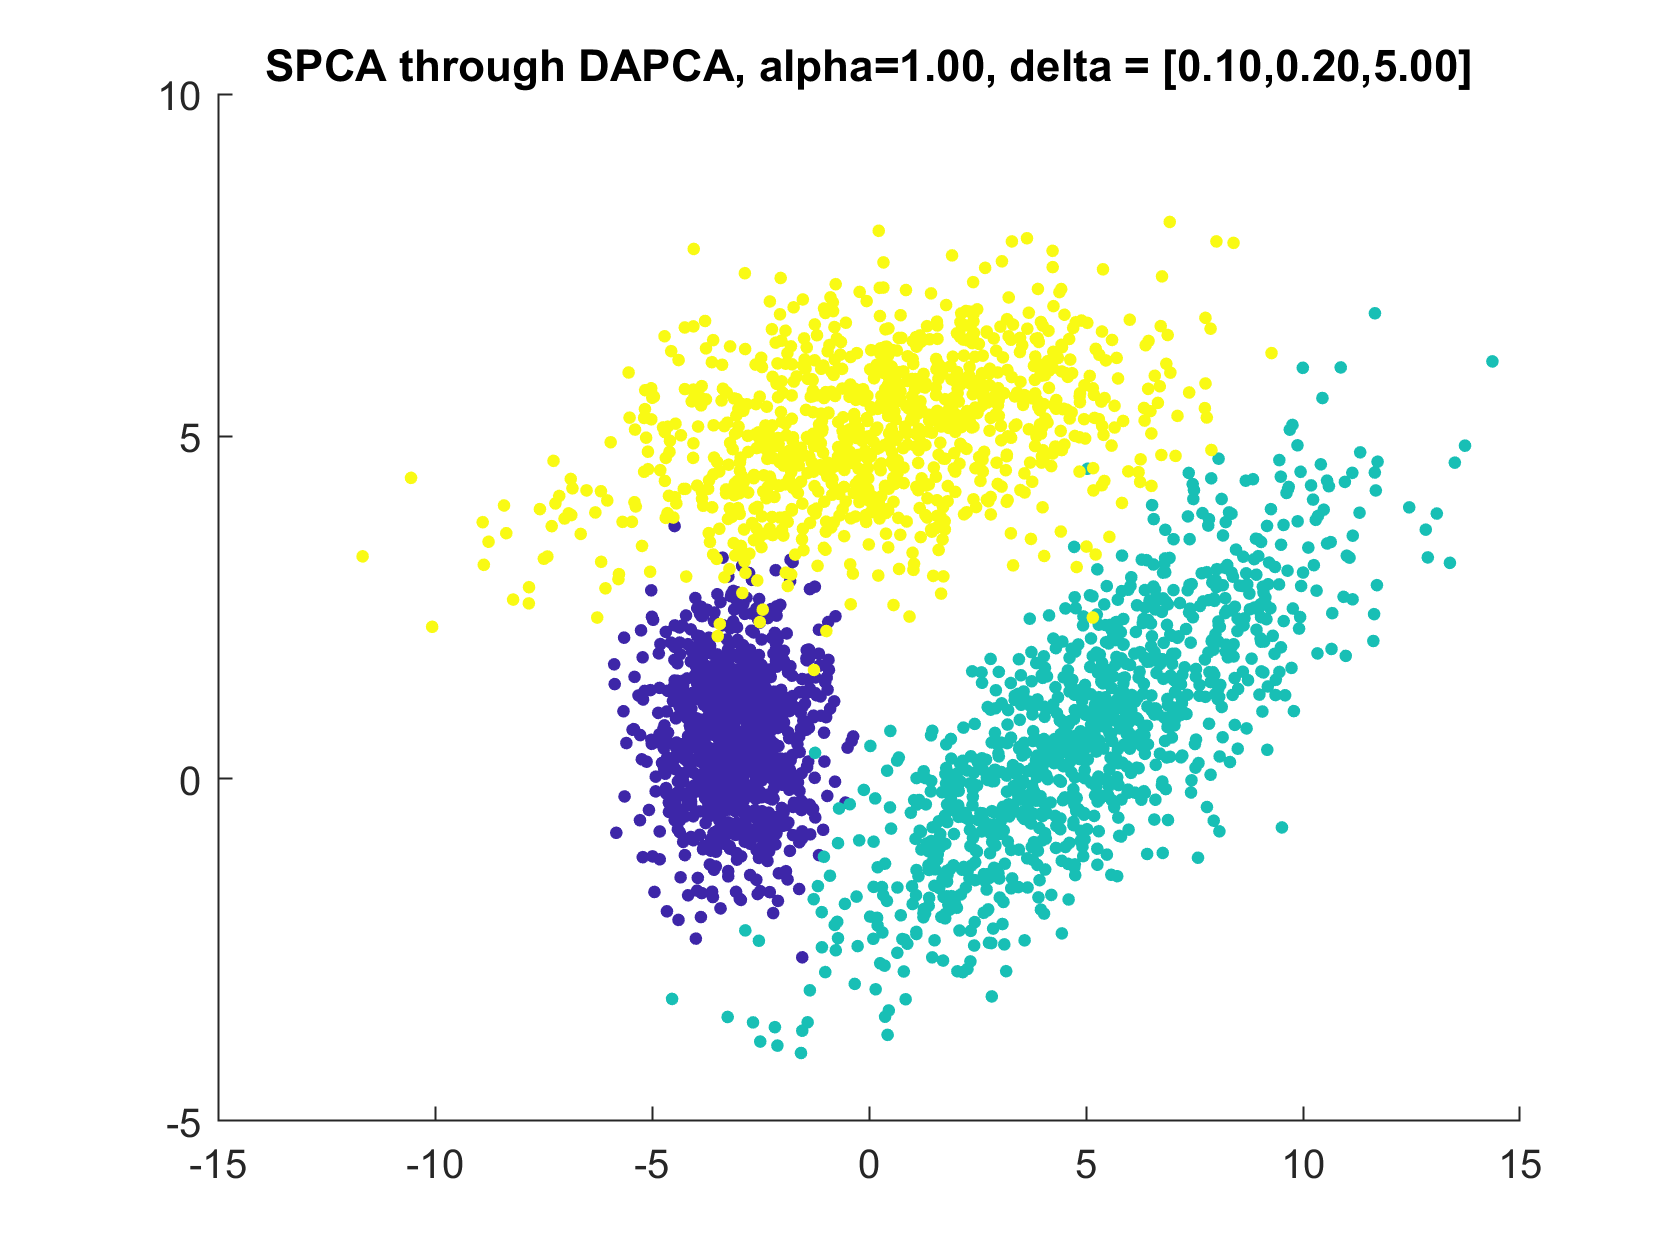

% Drawing
figure; 
scatter(PXd(:,1),PXd(:,2),10,labels,'filled'); 
title(sprintf('SPCA through DAPCA, alpha=%4.2f, delta = [%4.2f,%4.2f,%4.2f]', alpha, delta));
saveFigures(sprintf('Figures\\DAPCA_alpha_%4.2f_delta_[%4.2f,%4.2f,%4.2f].png', alpha, delta));

## Figure with Y for comparison

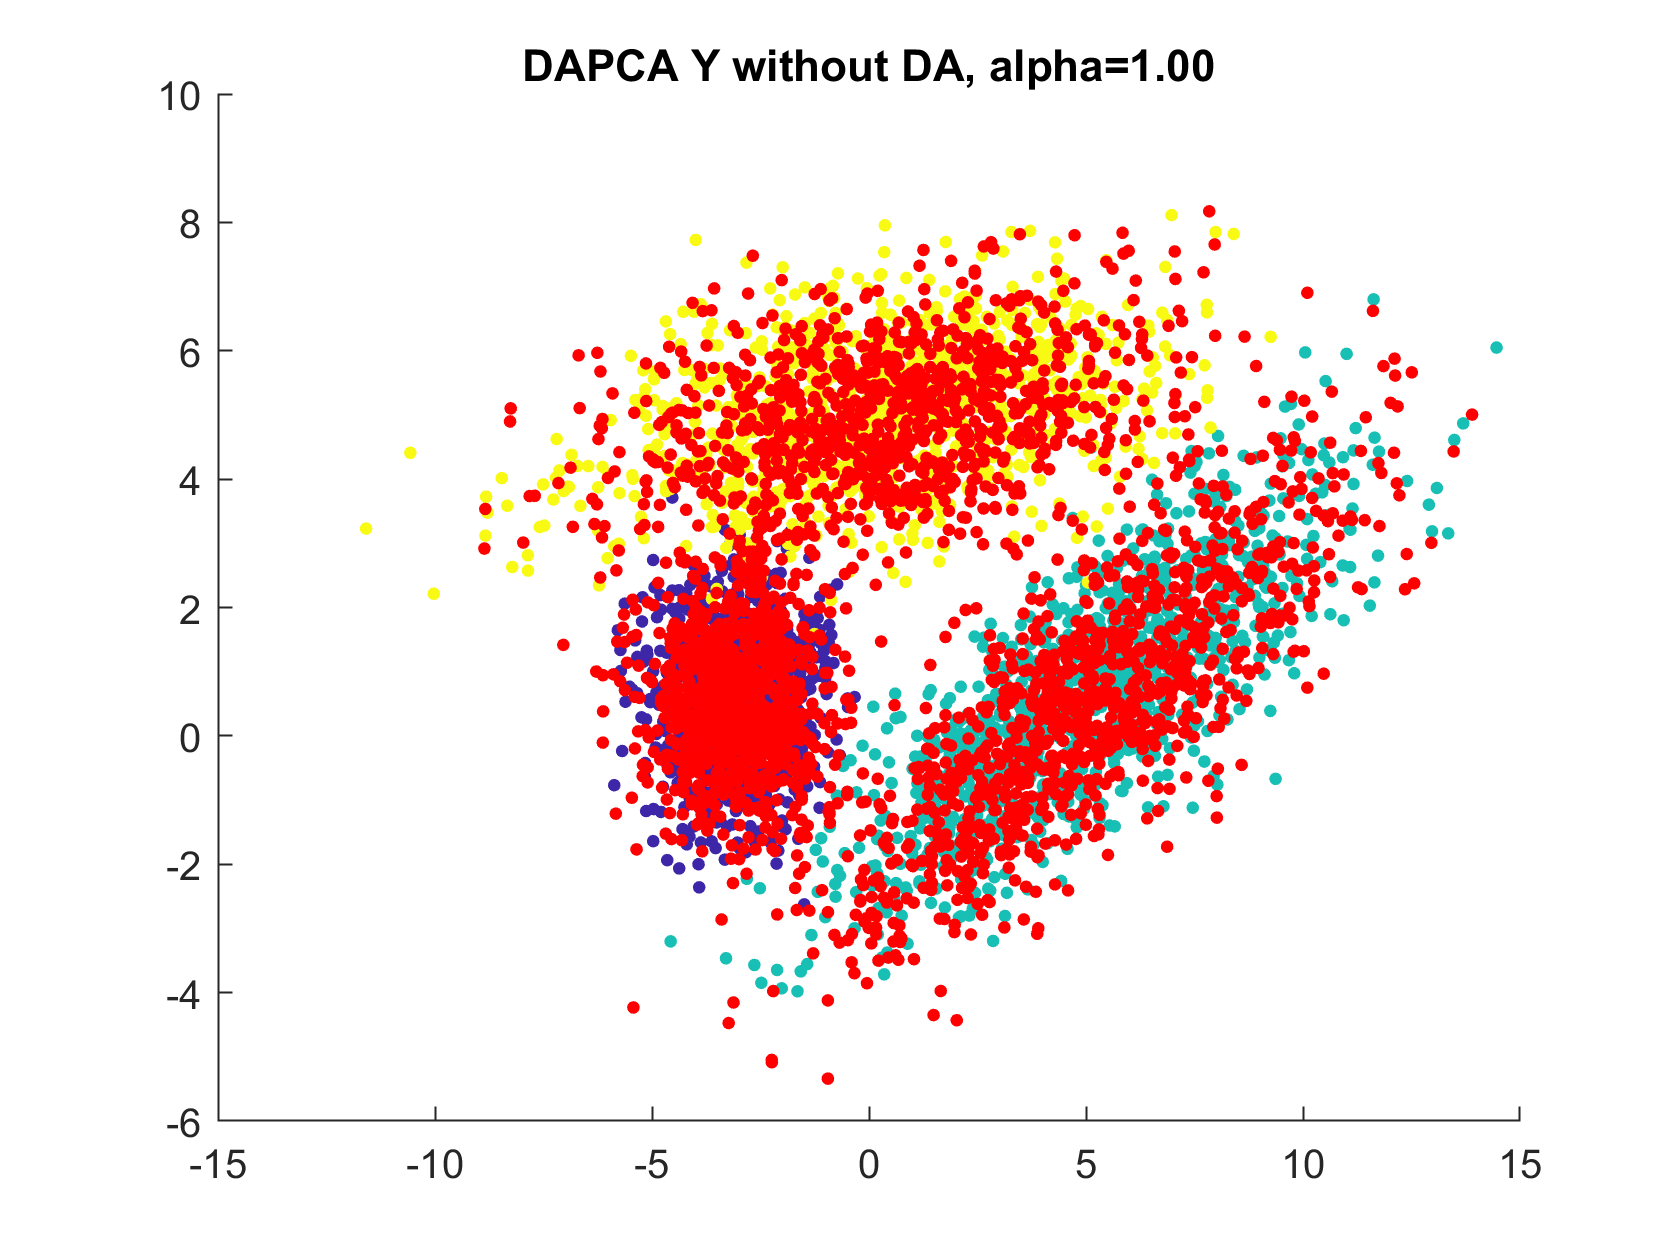

PY = Y * V1;
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
hold on;
scatter(PY(:,1),PY(:,2),10,'r','filled'); 
title(sprintf('DAPCA Y without DA, alpha=%4.2f', alpha));
saveFigures(sprintf('Figures\\DAPCA Y without Y in search, alpha %4.2f.png', alpha));

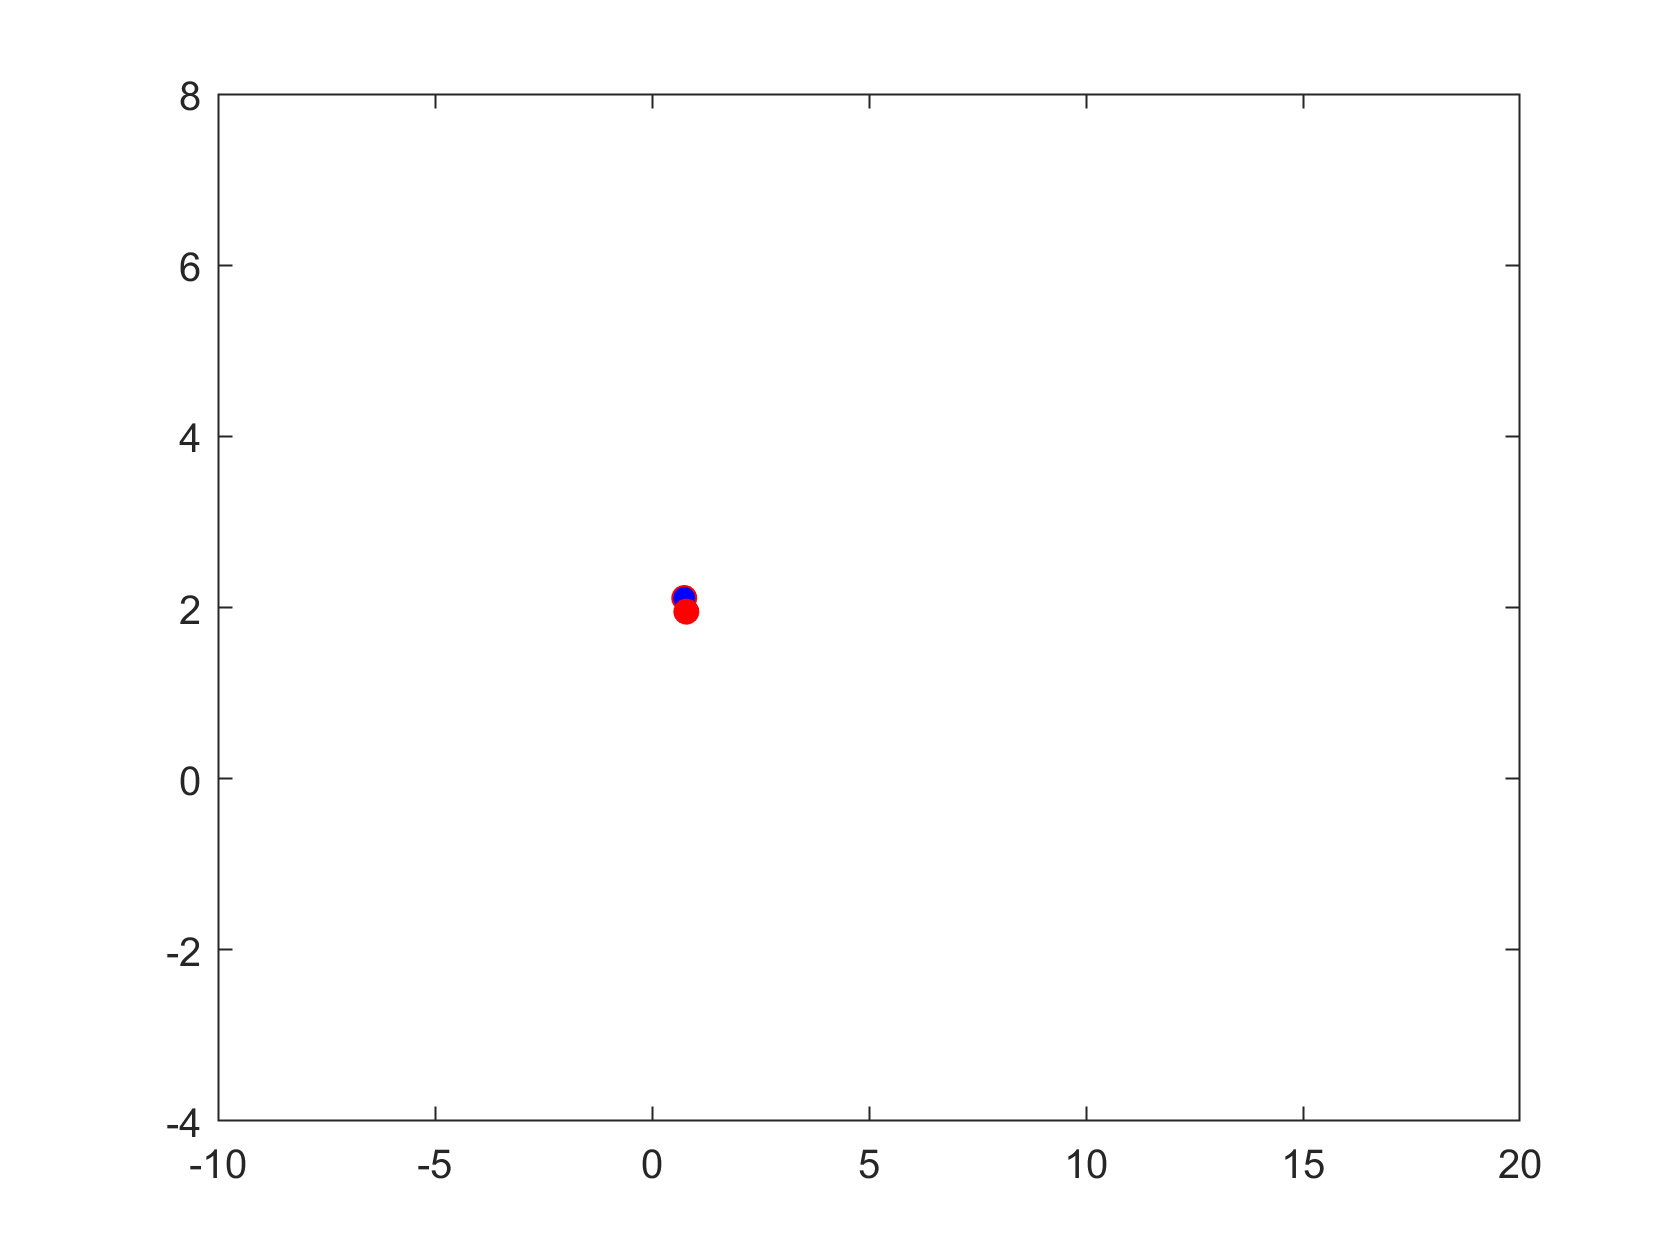

% Draw centroids
figure
mi = mean(PX);
plot(mi(1),mi(2),'or','markerfacecolor', 'b');
hold on;
mi = mean(PY);
plot(mi(1),mi(2),'or','markerfacecolor', 'r');
xlim([-10, 20]);
ylim([-4, 8]);
saveFigures(sprintf('Figures\\Centroids DAPCA Y without Y in search, alpha %4.2f.png', alpha));

## Redraw for shifted Y

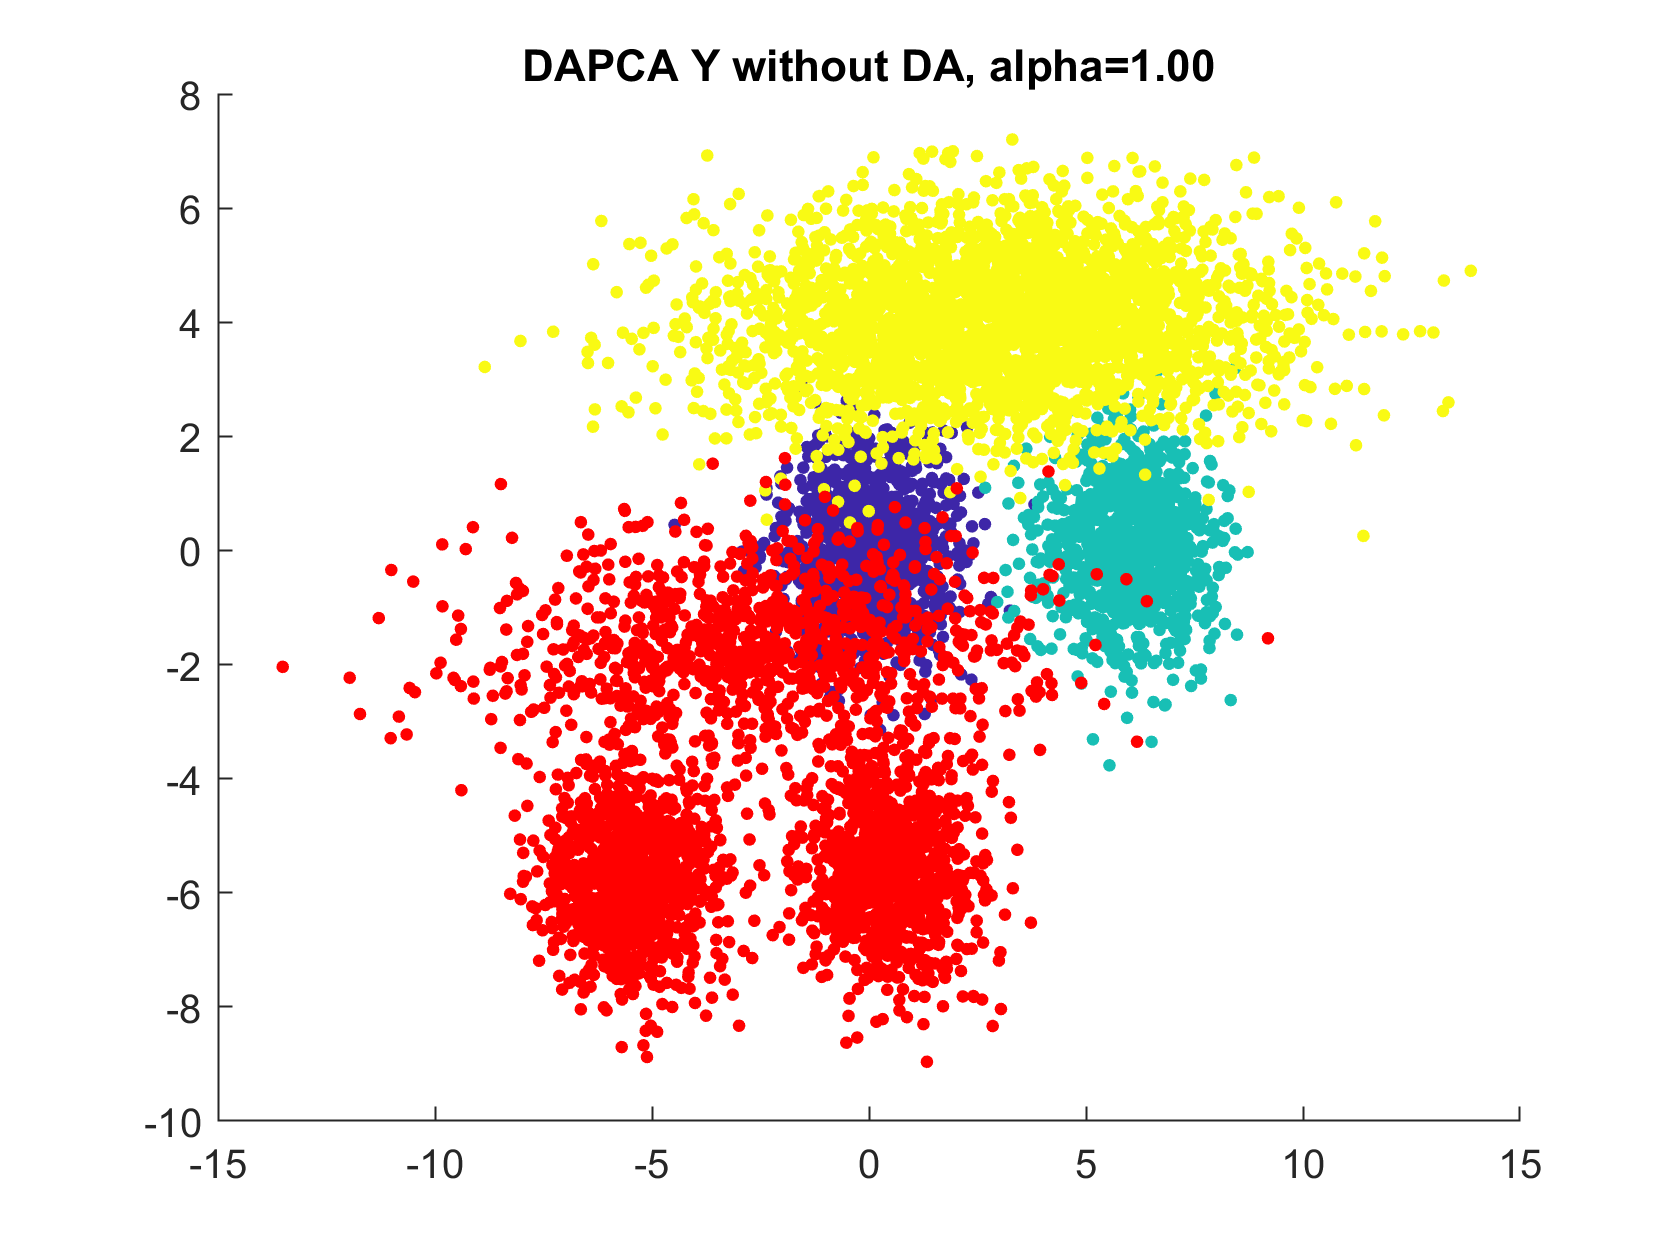

PY = (Y - 5) * V1;
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
hold on;
scatter(PY(:,1),PY(:,2),10,'r','filled'); 
title(sprintf('DAPCA Y without DA, alpha=%4.2f', alpha));
saveFigures(sprintf('Figures\\DAPCA SY without Y in search, alpha %4.2f.png', alpha));

## Repulsion in Y

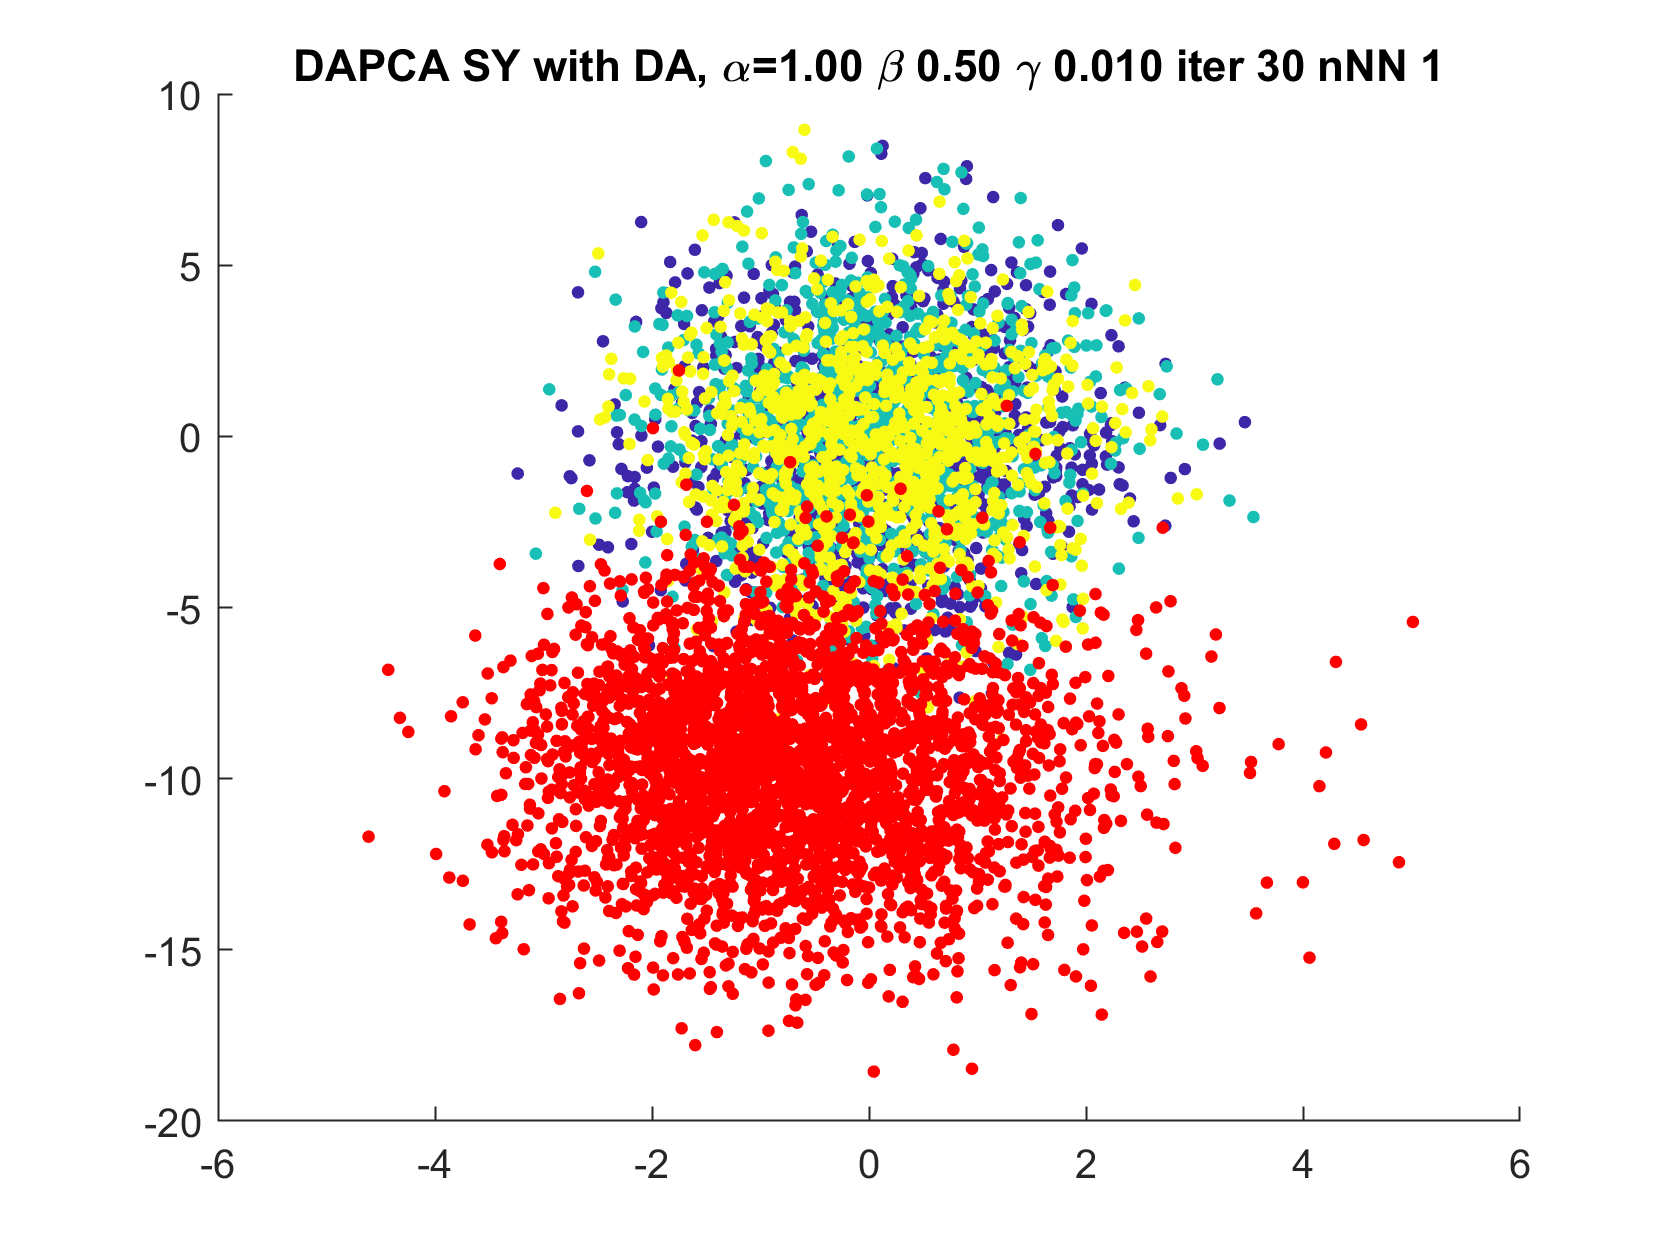

beta = 0.5;
delta = 1;
alpha = 1;
gamma = 0.01;
maxIter = 30;
SY = Y - 5;
kNN = 1;
[V, D, PX, PY] = DAPCA(X, labels, SY, 2, 'alpha', alpha, 'beta', beta, 'gamma', gamma, 'maxiter', maxIter, 'kNN', kNN);
% Draw
figure; 
scatter(PX(:,1), PX(:,2), 10, labels, 'filled'); 
hold on;
scatter(PY(:,1),PY(:,2),10,'r','filled'); 
title(sprintf('DAPCA SY with DA, \\alpha=%4.2f \\beta %4.2f \\gamma %5.3f iter %d nNN %d', alpha, beta, gamma, maxIter, kNN));
saveFigures(sprintf('Figures\\DAPCA Y with DA, alpha %4.2f beta %4.2f gamma %5.3f iter %d nNN %d.png', alpha, beta, gamma, maxIter, kNN));

## Recalculation for three steps

PC1 = [];
PC2 = [];
meanDist = [];
for maxIter = 1:3
    [V, D, PX, PY] = DAPCA(X, labels, SY, 2, 'alpha', alpha, 'beta', beta, 'gamma', gamma, 'maxiter', maxIter, 'kNN', kNN);
    PC1 = [PC1, V(:, 1)];
    PC2 = [PC2, V(:, 2)];
    meanDist = [meanDist, sum((mean(PX) - mean(PY)) .^ 2)];
    disp(meanDist)
end

    6.5695

    6.5695    6.5796

    6.5695    6.5796    6.5798



Angles calculation

tmp = PC1' * PC1;
tmp(tmp > 1) = 1;
PC1a = acosd(tmp);
tmp = PC2' * PC2;
tmp(tmp > 1) = 1;
PC2a = acosd(tmp);

## Comparison of V with the first elements of PC1 and PC2

ang1 = acosd(V(:, 1)' * PC1(:, 1));
ang2 = acosd(V(:, 2)' * PC2(:, 1));
mDist = sum((mean(PX) - mean(PY)) .^ 2);